clc;
clear all;
close all;
tic

Init

% number of tx antennas
numTx = 4;
% number of rx antennas
numRx = 4;

% modulation order (16-QAM)
M = 16;

% number of transmitted symbols (the larger the more precise the results will be)
% num_symbols = 49152; % 8 * 12 * 16 * 32
num_symbols = 24576; % 16 * 16 * 12 * 8
% num_symbols = 6144; % 16 * 12 * 8 * 4
% generate random symbols 
symbols = randi([0 M-1], 1, num_symbols);

% array of ones with length equal to number of tx antennas
deltas = ones(1,numTx);

% points to plot
points = 20;
% min and max value for snr
snr_min = 15;
snr_max = 35;

% generates an array of SNR values in the range [snr_min, snr_max] with a length equal to points
snr=linspace(snr_min,snr_max,points);

% arrays of zeros with length equal to the length of SNR values
ser_vblast = zeros(1,length(snr));
ser_zf = zeros(1,length(snr));

Modulation

% modulate input signal x using QAM with specified modulation order M
xmod = qammod(symbols, M);

% reshape xmod into a matrix with number of rows equal to number of tx antennas and 
% number of columns equal to number of symbols/number of tx antennas
xmod=reshape(xmod,numTx,num_symbols/numTx);

% Kronecker tensor product of xmod and deltas
xmod=kron(xmod,deltas);

Rayleigh channel

% initialize the matrix h to represent Rayleigh channel fading
% each row of h represents a fading channel between a tx antenna and a rx antenna
% generate a random channel for each fading channel using normal distribution
h = (1/sqrt(2)) * (randn(numTx * numRx, num_symbols/numRx) + 1i * randn(numTx * numRx, num_symbols/numRx));

% reshape h into a matrix with number of rows equal to number of tx antennas and number of columns equal to number of symbols
H = reshape(h, numTx, num_symbols);

% calculate the dot product of H and xmod and sum on the columns
tmp = sum(H .* xmod,1);

% reshape the result into a matrix with number of rows equal to number of rx antennas and number of columns equal to number of symbols/number of rx antennas
y = reshape(tmp, numRx, num_symbols/numRx);

% reshape h into a 3D matrix with dimensions equal to number of tx antennas, number of rx antennas, and number of symbols/number of rx antennas
H=reshape(h,numTx,numRx,num_symbols/numRx);

Receiver

for k=1:length(snr) % loop through each snr value
    % generate noise signal
    N1 = 1 / sqrt(2) * (randn(1,num_symbols)+1i * randn(1,num_symbols)); 
    % reshape the noise signal
    N1 = reshape(N1, numRx, num_symbols/numRx); 
     
    % add noise to received signal
    ynoisy=y+10^(-(snr(k)-10 * log10(M))/20) *N1; 
    % reshape the received signal with noise
    ynoisy=reshape(ynoisy,numRx,1,num_symbols/numRx); 

    % --------------------- VBLAST --------------------- %     
    y_final_vblast = vblast_demodulation(ynoisy, H, num_symbols, numRx);
    y_final_vblast = reshape(y_final_vblast, 1, []); 
    
    % Calculate the symbol error rate
    [~, tmp_ser_vb]=symerr(symbols,y_final_vblast); 
    ser_vblast(k)=tmp_ser_vb/log2(M);     
    % -------------------------------------------------- %
    
    
    % ----------------------- ZF ----------------------- %
    % Compute received signal matrix using zero_forcing_equalization function
    rcvd_zf = zero_forcing_equalization(num_symbols, numRx, H, ynoisy);
    
    % Demodulate the received signal
    y_final_zf = qamdemod(reshape(rcvd_zf, 1, num_symbols), M);
    % Calculate the symbol error rate
    [~, tmp_ser_zf] = symerr(symbols, y_final_zf);
    ser_zf(k) = tmp_ser_zf / log2(M);
    % -------------------------------------------------- %
    
end

Plot the results

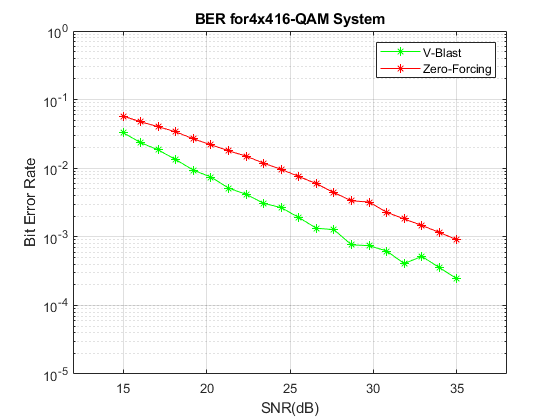

semilogy(snr,ser_vblast,'g-*');
hold on;
semilogy(snr,ser_zf,'r-*');
title({ strcat('BER for ', num2str(numTx), 'x' , num2str(numRx), ' ', num2str(M), '-QAM System')})
legend('V-Blast','Zero-Forcing');
xlabel('SNR(dB)');
ylabel('Bit Error Rate');
xlim([snr_min-3 snr_max+3])
ylim([10^-5 10^0])
grid on;

toc

Elapsed time is 84.213631 seconds.
